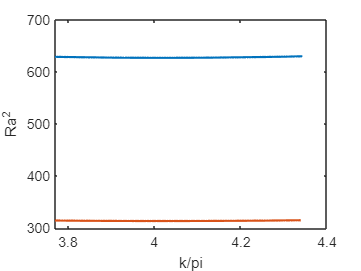

clear all
close all
clc


for ind=1:2
    if ind==1
        load sigma_H=6.mat
    end
    if ind==2
        load sigma_H=-6.mat
    end

    l=1;
    l2=1;
    for j=1:length(kk)
        flag=0;
        n=1;
        while n<=length(RR)-1 && flag==0
            if (real(sigma(n,j))<0 && real(sigma(n+1,j))>0 && abs(imag(sigma(n+1,j)))<10^(-6)) || (real(sigma(n,j))>0 && real(sigma(n+1,j))<0 && abs(imag(sigma(n+1,j)))<10^(-6))
                if flag==0
                    realRa(l)=RR(n);
                    realwavenumber(l)=pi*kk(j);
                    l=l+1;
                    flag=1;
                end
            end
            n=n+1;
        end
    end
    plot(realwavenumber,realRa.^2,'LineWidth',1.5)
    xlabel('k/pi')
    ylabel('Ra^2')
    hold on
    [Rc(ind),index]=min(realRa.^2);
    wavec(ind)=realwavenumber(index);
    realRa=[];
    realwavenumber=[];

end

save casi_noti_TU=7.mat Rc wavec